# **Evaluación 2 | Procesamiento de señales e imágenes 2023-1**

*Estudiante: Nícolas Farfán Cheneaux | 27391503-6*

*Profesor: Max Chacón*

*Ayudante: Luis Corral*

## Pregunta 1

Según la propiedad de la **Convolución del tiempo**, establece que


$$\begin{array}{l}
\textrm{Si}\\
F\left\lbrace x_1 \right\rbrace =X_1 \left(w\right)\;\textrm{and}\;F\left\lbrace x_2 \right\rbrace =X_2 \left(w\right)\\
\textrm{Entonces}\\
F\left\lbrace x_1 *x_2 \right\rbrace =X_1 \left(w\right)\;X_2 \left(w\right)\\
\left(\textrm{Fuente}:\textrm{Digital}\;\textrm{Signal}\;\textrm{Proccesing},\;\textrm{Kumar}\;\textrm{página}\;373\right)
\end{array}$$


Pasos a seguir:

1) Se lee el archivo que contiene la señal de entrada $x\left\lbrack n\right\rbrack$ **ruido.wav** y se carga **rifiltro.mat **con la respuesta al impulso $h\left\lbrack n\right\rbrack$.

2) Se realiza el primer método es decir el de la convolución de la entrada del sistema $x\left\lbrack n\right\rbrack$ y respuesta al impuslo $h\left\lbrack n\right\rbrack$ y se obtiene la salida del sistema $y\left\lbrack n\right\rbrack$ en el dominio del **tiempo** y posterioremente se aplica la **Transformada Rápida de Fourier (fft) **en el dominio de la **frecuencia**.

3) Se realiza el segundo método es decir aplicando la **Transformada Rápida de Fourier **tanto a la entrada y respuesta al impulso para posteriormente multiplicarlos en el dominio de la **frecuencia**.

4) Se realiza la **Inversa Transformada de Fourier (ifft) **con el resultado obtenido, obtiendo la magnitud de la señal resultante en el dominio del **tiempo**.

5) Finalmente se grafica en el dominio de la **frecuencia (aplicando fft) **ambos métodos, comprobando que son equivalentes viendo efectivamente una disminución del tono contaminante y por lo tanto la propiedad de cumple.

clearvars
% Lectura de la señal de voz x[n] contaminada
[x_n, Fs] = audioread("ruido.wav");

% Se carga la respuesta al impulso h[n] (h)
load('rifiltro.mat');

% Se verifica que h se haya cargado correctamente
h

h =     0.0065
    0.0494
    0.1662
    0.3198
    0.3735
    0.2376
    0.0069
   -0.1313
   -0.1018
    0.0059



% Se acota a la frecuencia de muestro la señal de entrada y la respuesta al
% impuslo
x_n = x_n(1:Fs)

x_n =          0
    0.0122
    0.0035
   -0.0112
   -0.0068
    0.0092
    0.0095
   -0.0065
   -0.0114
    0.0031


h_n = h(1:Fs)

h_n =     0.0065
    0.0494
    0.1662
    0.3198
    0.3735
    0.2376
    0.0069
   -0.1313
   -0.1018
    0.0059



% Método 1
% Convolución para obtener la salida del sistema y[n] = x[n] * h[n]
% Dominio del Tiempo
% Se utiliza el parámetro same para obtener una señal de igual tamaño que
% la de entrada (x[n])
y_n = conv(x_n, h_n, 'same');

% Dado que FFT es simétrica, se obtienen resultados del mismo largo que la
% secuencia de entrada

% Transformada de Fourier de la salida del sistema y[n]
% (Dominio de la Frecuencia)
f_y = fft(y_n)

f_y = 1.0e+02 *

   0.0076 + 0.0000i
  -0.0178 + 0.0146i
   0.0337 - 0.0030i
  -0.0126 - 0.0013i
   0.0293 - 0.0218i
  -0.0254 + 0.0058i
   0.0601 - 0.0573i
  -0.1418 - 0.0483i
   0.0148 + 0.1268i
   0.0501 - 0.0499i



% Método 2
% Salida del sistema usando la propiedad de la multiplicación
% Transformada Rápida de Fourier de la señal de entrada x[n] e impulso h[n]
X_jw = fft(x_n)

X_jw = 1.0e+02 *

   0.0186 + 0.0000i
   0.0049 - 0.0186i
   0.0433 + 0.0082i
   0.0083 - 0.0121i
   0.0284 - 0.0068i
   0.0314 - 0.0187i
   0.0510 - 0.0468i
   0.1525 + 0.0424i
   0.0041 + 0.1302i
  -0.0416 + 0.0488i


H_jw = fft(h_n)

H_jw =    1.0000 + 0.0000i
   1.0000 - 0.0004i
   1.0000 - 0.0009i
   1.0000 - 0.0013i
   1.0000 - 0.0017i
   1.0000 - 0.0021i
   1.0000 - 0.0026i
   1.0000 - 0.0030i
   1.0000 - 0.0034i
   1.0000 - 0.0039i



% Multiplicación Vectorial X[jw]H[jw] (X y H tienen el mismo tamaño)
% Dominio de la Frecuencia
Y_jw = X_jw .* H_jw

Y_jw = 1.0e+02 *

   0.0186 + 0.0000i
   0.0049 - 0.0186i
   0.0433 + 0.0081i
   0.0082 - 0.0122i
   0.0284 - 0.0069i
   0.0313 - 0.0188i
   0.0509 - 0.0469i
   0.1526 + 0.0420i
   0.0045 + 0.1302i
  -0.0414 + 0.0489i



% Dominio del Tiempo
% Magnitud de la señal resultante en el dominio del tiempo al aplicar la
% inversa transformada de Fourier
invY_jw = ifft(Y_jw)

invY_jw =     0.0337
    0.0323
    0.0245
    0.0119
    0.0014
   -0.0031
   -0.0032
   -0.0019
    0.0003
    0.0025


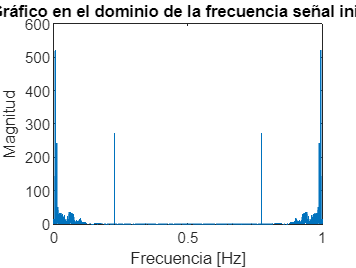


% Graficar la magnitud de la señal resultante en el dominio de la frecuencia
N = length(y_n(1:Fs));  % Longitud de la señal resultante
f_hz = (0:N-1) / N;  % Eje de frecuencias

% Grafico en el dominio de la frecuencia antes de aplicar el filtro
figure;
plot(f_hz, abs(X_jw));
title('Gráfico en el dominio de la frecuencia señal inicial');
xlabel('Frecuencia [Hz]');
ylabel('Magnitud');

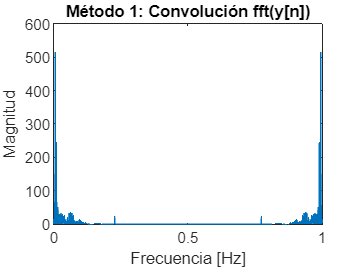


% Método 1: FFT de la convolución
figure;
plot(f_hz, abs(f_y));
title('Método 1: Convolución fft(y[n])');
xlabel('Frecuencia [Hz]');
ylabel('Magnitud');

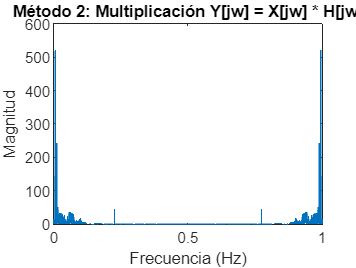


% Método 2.1: Gráfico 1 FFT de la IFFT de Y_jw
figure;
plot(f_hz, abs(fft(invY_jw)));
title('Método 2: Multiplicación Y[jw] = X[jw] * H[jw]');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');


% Notar que es equivalente a simplemente graficar la magnitud de Y_jw que
% hacer la transformada rápida de Fourier de la Inversa de la Transformada
% Rápida de Fourier, se obtiene el mismo resultado.
% No se grafica por términos prácticos

%Método 2.2: Gráfico 2 Y_jw
%figure;
%plot(f_hz, abs(Y_jw));
%title('Método 2: Propiedad Multiplicación Y[jw]');
%xlabel('Frecuencia (Hz)');
%ylabel('Magnitud');

#### Análisis de los resultados

Se puede observar que antes de aplicar el filtro la primera señal tiene una magnitud de la frecuencia alta en diversos puntos, es más notorio en los valores centrales cerca de 0.5 se tiene frecuencias de altas magnitudes.

Posteriormente a aplicar el filtro **h** mediante los 2 métodos vistos, se obtiene resultados relativamente similares, dado que en ambos gráficos se puede observar una disminución del tono puro de alta frecuencia, es decir, se disminuye la contribución de la señal contaminante.

## Pregunta 2

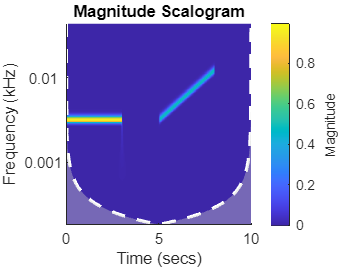

senal(); % Se carga el escalograma Frecuencia/Tiempo

### Comportamiento Temporal y Espectral

Se puede observar entre 0 y 3 segundos un patrón periódico / recurrente de 0.1 Hz. También hay una predominancia de la frecuencia de 0.1 Hz, se tiene una zona de alta energía entre 0 y 3 segundos y se tiene un crecimiento constante de 0.1 Hz a 1 Hz de 3 segundos aprox. y un pico de 1 Hz en 8 segundos.

#### Energía

Entre 0 y 3 segundos se observa la amplitud máxima de la señal (superior a 0.9 Hz).

#### Eventos transitorios

Entre 3 y 5 segundos hay un cambio repentino, dado que de una magnitud alta se pasa a directamente no observar ninguna frecuencia, y posteriormente de 5 a 8 segundos se observa un patrón de aumento de la frecuencia de forma lineal en una magnitud constante (0.5 Hz) aproximadamente.

## Pregunta 3

Para esta pregunta se ha dividido el procedimiento en 3 partes

#### **Justificación polos y ceros**

**-> **Si colocamos el cero real en z = -1 y el polo real θ = 0 se obtiene un filtro pasa bajos con la frecuencia de conrte 6000Hz que transformando a radianes se debe verificar que sea fc ≤ **π**/2.

#### 1) Diseño del filtro y gráfico de plano Z

clearvars
% Lectura del archivo de audio
[x_n, Fs] = audioread("white_noise_263s_Matlab10_EDIT.wav")

x_n =    -0.0089
    0.0060
    0.0123
   -0.0011
   -0.0015
    0.0114
   -0.0269
    0.0113
   -0.0164
   -0.0251


Fs = 48000


Fs % Frecuencia de muestreo en Hz

Fs = 48000

fc_hz = 6000 % Frecuencia de corte en Hz

fc_hz = 6000

fc = 2*pi*fc_hz/Fs; % Frecuencia de corte en radianes

% Dado que  el filtro utilizado fue tomado del laboraotio n°5, la frecuencia de corte debe ser
% menor a pi/2 para ser utilizado
if fc < pi/2
    disp("Se obtendrán buenos resultados")
end

Se obtendrán buenos resultados


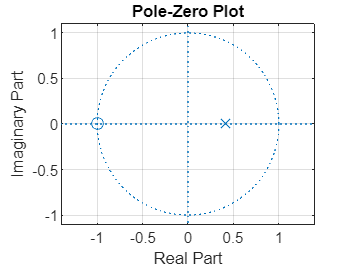


% Se obtendrán buenos resultados al aplicar este filtro por lo que el
% procedimiento puede seguir

% Alpha fijado en -1 (Parámetro usado para el cálculo de coeficientes del
% filtro) PUEDE SER MODIFICADO
alpha = -1;

% Radio de los polos y ceros plano Z
r = (0.001:0.001:0.999);

% Se calcula la respuesta en frecuencia del filtro en la frecuencia 0
H_0 = 2 * sqrt(1-2*alpha*cos(0)+alpha^2)./sqrt(1-2*r*cos(0)+r.^2);

% Se calcula la respuesta en frecuencia del filtro en la frecuencia de
% corte fc
H_fc = 2 * sqrt(1-2*alpha*cos(fc)+alpha^2)./sqrt(1-2*r*cos(fc)+r.^2);

% Indice "d" del vector "r" menor diferencia entre H_0/H_fc y la raiz de 2
[~, d] = min(abs((H_0./H_fc)-sqrt(2)));

% Polo del filtro como el valor correspondiente a "r" en el indice "d",
% ángulo del polo 0 grados.
pole = [abs(r(1,d)) 0];

% Cero del filtro con radio alpha y ángulo 180 grados.
zero = [abs(alpha) 180];

% Polos de radio/ángulo a número complejo
n_polos = size(pole, 1);
if n_polos > 0
    polos_c = zeros(n_polos, 1);
    for i = 1:n_polos
        polos_c(i, 1) = pole(i, 1)*exp(deg2rad(pole(i, 2))*1i);
    end
else
    polos_c = [];
end

% Ceros de radio/ángulo a número complejo
n_zeros = size(zero, 1);
if n_zeros > 0
    zeros_c = zeros(n_zeros, 1);
    for i = 1:n_zeros
        zeros_c(i, 1) = zero(i, 1)*exp(deg2rad(zero(i, 2))*1i);
    end
else
    zeros_c = [];
end

% Gráfico de polos y ceros en el plano Z
zplane(zeros_c, polos_c)
grid

#### **2) Repuesta de la frecuencia del filtro pasa bajos**

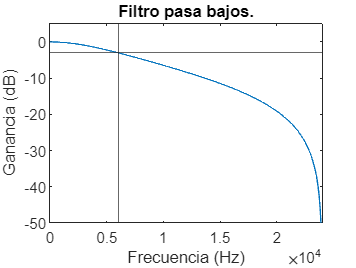

% Cálculo y gráfico de la respuesta de frecuencia del filtro pasa bajos
% Usa los polos y ceros específicados

% Crea la función de transferencia representada por los coeficientes "a" y
% "b", el argumento 1 es que no hay ganancia adicional en el filtro
[b, a] = zp2tf(zeros_c, polos_c, 1); 

% Calcula la respuesta al filtro, con los coeficientes "a" y "b" y con 320
% puntos de frecuencia donde se calculará la respuesta de frecuencia y de
% muestreo
[h, ~] = freqz(b, a, 320, Fs);

% Factor de normalización "K" para que la ganancia de la respuesta de
% frecuencia sea 1, valor máximo en magnitud h y luego su inverso
K = 1/max(abs(h));

% Respuesta del filtro normalizado 
[h, f] = freqz(K*b, a, 320, Fs);

% Gráfico de la magnitud de la respuesta de frecuencia en decibelios en
% función de la frecuencia. Escala logarítmica a decibelios.
figure
plot(f, 20*log10(abs(h)))

% Línea horizontal en -3dB
yline(-3)

% Se convierte fc a radianes, para graficar una línea
xline((fc/(2*pi))*Fs)
ylim([-50 5])
xlim([0 Fs/2])
title('Filtro pasa bajos.')
ylabel('Ganancia (dB)')
xlabel('Frecuencia (Hz)')

**3) Aplicación del filtro a los primeros 3 segundos del archivo de audio ***white_noise_263s_Matlab10_EDIT.wav*

% Corta el audio a los primeros 3 segundos
x_n = x_n(1:Fs*3);

% Agrega un tono puro de 60Hz a la señal de audio (1/4RMS(de la señal))
% De 0 a 3 segundos, cada 0.01
% Se modifica 1/Fs por 0.01 por cuestiones de memoria (out of memory)
x_n = x_n + (rms(x_n)/4)*sin(2*pi*60*(0:0.01:3))

x_n =    -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064   -0.0089   -0.0115   -0.0049   -0.0130   -0.0064
    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019    0.0085    0.0060    0.0035    0.0101    0.0019   

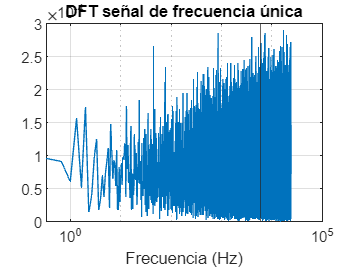


% Aplicación de la transformada rápida de Fourier a la señal original
X_ejw = fft(x_n);

% Largo de la señal original
N = length(x_n); 
% Mitad positiva de la transforamada de Fourier dado que es simétrica en el dominio de la frecuencia
X_ejw = X_ejw(1:round(N/2)+1);
% Vector de frecuencias correspondientes
f_hz = Fs*(0:round(N/2))/N;

figure
semilogx(f_hz,2*abs(X_ejw)/N) % grafico con eje x logaritmico, x2 para compensar la reducción de la amplitud y se divide por Ny para normalizar la amplitud
xline(fc_hz) % Línea vertical que representa la frecuencia de corte 6000Hz
grid on
title('DFT señal de frecuencia única')
xlabel('Frecuencia (Hz)')

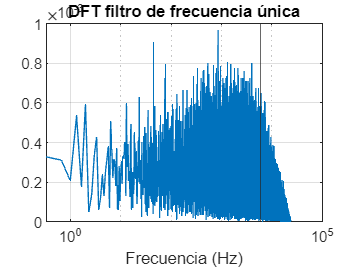


% Aplica el filtro con los coeficientes a y b a la señal x_n
y = filter(b,a,x_n);

% Aplicación de la transformada rápida de Fourier a la señal con el filtro
Y_ejw = fft(y);
Ny = length(y); % Largo de la señal resultante "y"

% Mitad positiva de la transforamada de Fourier dado que es simétrica en el dominio de la frecuencia
Y_ejw = Y_ejw(1:round(Ny/2)+1);

% Vector de frecuencias correspondientes
f_hzy = Fs*(0:round(Ny/2))/Ny;
figure
semilogx(f_hzy,2*abs(Y_ejw)/Ny) % grafico con eje x logaritmico, x2 para compensar la reducción de la amplitud y se divide por Ny para normalizar la amplitud
xline(fc_hz) % Línea vertical que representa la frecuencia de corte 6000Hz
grid on
title('DFT filtro de frecuencia única')
xlabel('Frecuencia (Hz)')

#### Análisis de los resultados

Cómo se puede observar si se coloca un **xline** o una **línea vertical **en el **eje x **representando la frecuencia de corte, se puede apreciar como el filtro pasa bajo, deja pasar las frecuencias bajas pero atenúa las frecuencias altas a partir de los **6000Hz**.